# Classifying Urban Sounds8K Dataset using MFCC and Machine Learning

Kevin Chng

## Overview :

            For this example, we are going to classify Urban sounds dataset using MFCC and Machine Learning. 

            For this project we will use a dataset called Urbansound8K. The dataset contains 8732 sound excerpts (<=4s) of urban sounds from 10 classes, which are:

- Air Conditioner

- Car Horn

- Children Playing

- Dog bark

- Drilling

- Engine Idling

- Gun Shot

- Jackhammer

- Siren

- Street Music

The accompanying metadata contains a unique ID for each sound excerpt along with it's given class name. A sample of this dataset is included with the accompanying git repo and the full dataset can be downloaded from [here](https://urbansounddataset.weebly.com/urbansound8k.html).    

## **Highlights : **

- preparing the real life data for [audiodatastore](https://www.mathworks.com/help/audio/ref/audiodatastore.html)

- Extract features using MFCC

- Train machine learning model using classification learner app

- deploy machine learning model to embedded devices or desktop application

## **Product Focus :**

- MATLAB

- Audio Toobox

- Statistics and Machine Learning Toolbox

- Signal Processing Toolbox

- DSP System Toolbox

**Written at 19 November 2019**

## **Load Data - Audiodatastore**

rng(1)
datafolder = "UrbanSound8K/structure";

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

%Split Data
%Should not as low as 0.5, but it help me to accerelate the training 
[trainDatastore, testDatastore] = splitEachLabel(ads,0.7,'randomized');

%Display the datastore and the number of speakers in the train datastore.
trainDatastore

trainDatastore =   audioDatastore with properties:

                       Files: {
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-0.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-10.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-11.wav'
                               ... and 6109 more
                              }
                      Labels: [Air Conditioner; Air Conditioner; Air Conditioner ... and 6109 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


trainDatastoreCount = countEachLabel(trainDatastore)

trainDatastoreCount = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner      700 
    Car Horn             300 
    Children Playing     700 
    Dog Bark             700 
    Drilling             700 
    Engine Idling        700 
    Gun Shot             262 
    Jackhammer           700 
    Siren                650 
    Street Music         700 


%Display the datastore and the number of speakers in the test datastore.
testDatastore

testDatastore =   audioDatastore with properties:

                       Files: {
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-1.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-20.wav';
                              ' ...\UrbanSound8K\structure\Air Conditioner\100852-0-0-27.wav'
                               ... and 2617 more
                              }
                      Labels: [Air Conditioner; Air Conditioner; Air Conditioner ... and 2617 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


testDatastoreCount = countEachLabel(testDatastore)

testDatastoreCount = 10×2 table
         Label          Count
    ________________    _____

    Air Conditioner      300 
    Car Horn             129 
    Children Playing     300 
    Dog Bark             300 
    Drilling             300 
    Engine Idling        300 
    Gun Shot             112 
    Jackhammer           300 
    Siren                279 
    Street Music         300 


## Visualize and Listen the Data (Wav. file)

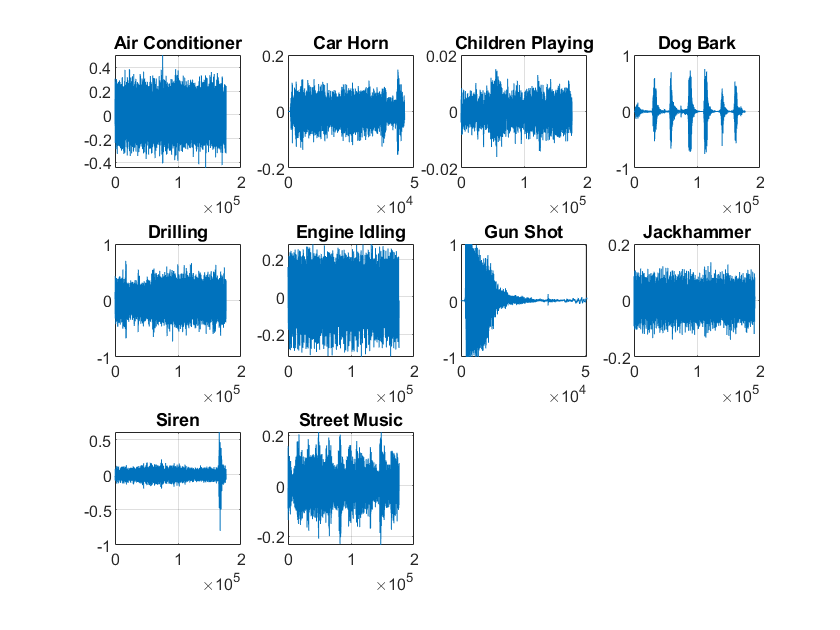

figure()
datafolder = "UrbanSound8K/structure";
currentfolder = pwd;
cd(datafolder);
listdir=dir;  
for i=3:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    subplot(3,4,i-2);
    [y,fs]=audioread(inside(4).name);
    plot(y(:,:)); 
    soundsc(y(:,:),fs);
    grid on;
    title(listdir(i).name)
    drawnow;
    pause(5)
    cd(strcat(currentfolder,'\',datafolder));
end

cd(currentfolder);

## **Extract Features - MFCC**

fs = 44100; %44.1khz
adstall = tall(trainDatastore);
% melspectrum, barkSpectrum, erbSpectrum
aFE = audioFeatureExtractor('SampleRate',44.1e3,'mfcc',true,'pitch',true, ...
    "Window",hamming(round(fs),"periodic"), ...
    "OverlapLength",fs*0.5);
specsTall = cellfun(@(x)extract(aFE,x),adstall,"UniformOutput",false);
specs = gather(specsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 6 min 0 sec
Evaluation completed in 6 min 0 sec


Average the value of MFCC features within the same audio file :

for i = 1:1:length(specs)
    specs_new{i,1} = mean(specs{i});
end

Create a table for features and label them

x1 = cell2mat(specs_new(1));
specstable = array2table(x1);
specstable.Labels(1) = trainDatastore.Labels(1);
specstable.Files(1) = trainDatastore.Files(1);
for i=2:length(specs_new)
    x1 = cell2mat(specs_new(i));
    specstable_temp = array2table(x1);
    specstable_temp.Labels = trainDatastore.Labels(i);
    specstable_temp.Files = trainDatastore.Files(i);
    try 
        specstable = [specstable;specstable_temp];
    end
end

## **Rank Features/Select Features**

Using fscmrmr, for detail or other methods, please refer to [https://www.mathworks.com/help/stats/feature-selection.html](https://www.mathworks.com/help/stats/feature-selection.html)

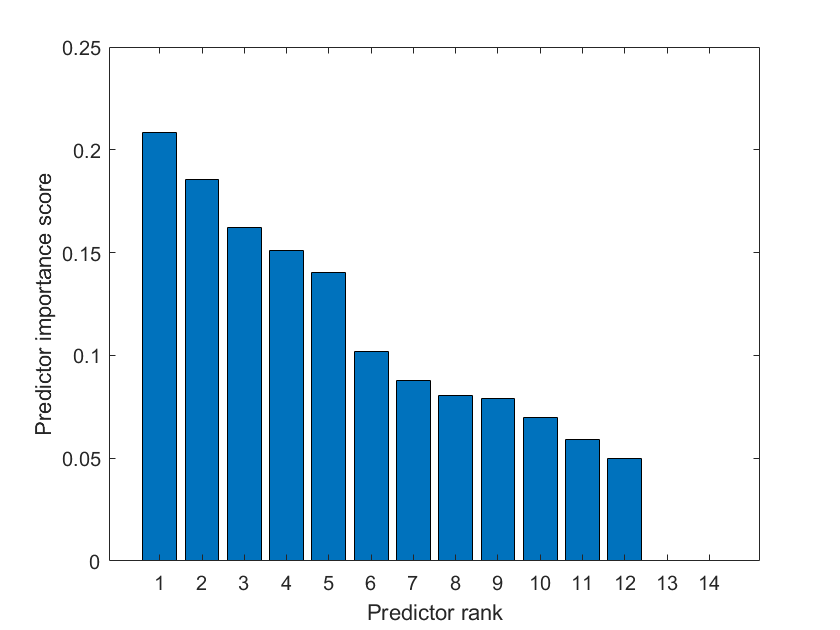

[idx,scores] = fscmrmr(specstable(:,1:14),specstable(:,15));
%% Create a bar plot of the predictor importance scores.
bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')

## Use PCA to visualize the data before Machine Learning Training

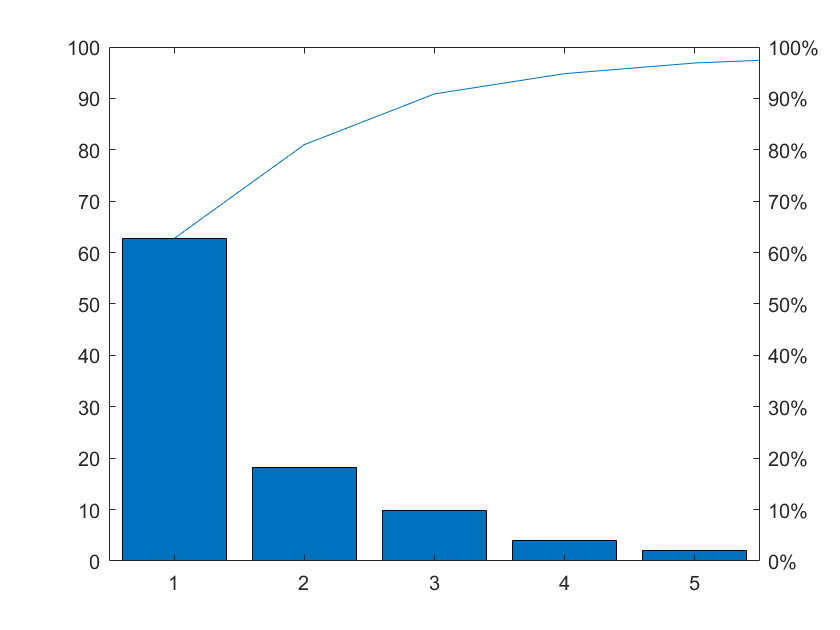

[coeff,score,latent,tsquared,explained] = pca(specstable{:,1:11});
figure()
pareto(explained)

First 3 component represent :

sum(explained(1:3))

ans =   90.868423703215072


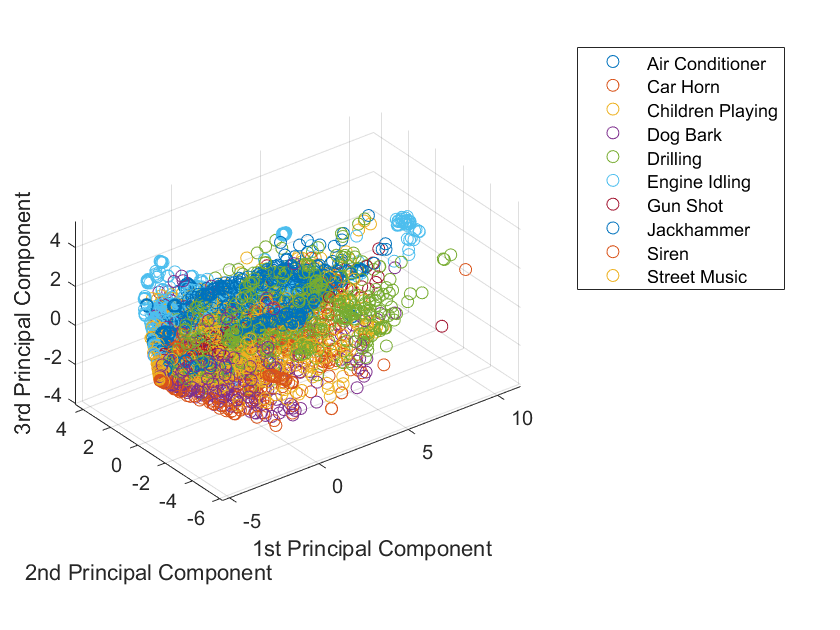

Data_Class = categorical(["Air Conditioner","Car Horn","Children Playing","Dog Bark","Drilling","Engine Idling","Gun Shot","Jackhammer","Siren","Street Music"]);
figure()
for i =1:1:length(categories(specstable.Labels))
scatter3(score(specstable{:,15}==Data_Class(i),1),score(specstable{:,15}==Data_Class(i),2),score(specstable{:,15}==Data_Class(i),3))
hold on
axis equal
end
legend(Data_Class)
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')
grid on
hold off

Observation : Great, look at the graph, it represent 90% of the data, and it looks positive, with visual inspoection, we seem can draw line to separate classes.

Rearrage the name of column in table

specstable.Properties.VariableNames{1} = 'x1';
specstable.Properties.VariableNames{2} = 'x2';
specstable.Properties.VariableNames{3} = 'x3';
specstable.Properties.VariableNames{4} = 'x4';
specstable.Properties.VariableNames{5} = 'x5';
specstable.Properties.VariableNames{6} = 'x6';
specstable.Properties.VariableNames{7} = 'x7';
specstable.Properties.VariableNames{8} = 'x8';
specstable.Properties.VariableNames{9} = 'x9';
specstable.Properties.VariableNames{10} = 'x10';
specstable.Properties.VariableNames{11} = 'x11';
specstable.Properties.VariableNames{12} = 'x12';
specstable.Properties.VariableNames{13} = 'x13';
specstable.Properties.VariableNames{14} = 'x14';

## **Machine Learning Training**

Using classification learner app to train the model and then export it back to workspace (Name the model as MFCCmodel)

- import specstable

- Train all models at first run

- Select the best model to do bayesian optimization

- Select the best model to impose higher cost matrix to certain misclassication classes.

- Export the model back to workspace

classificationLearner

Results : 

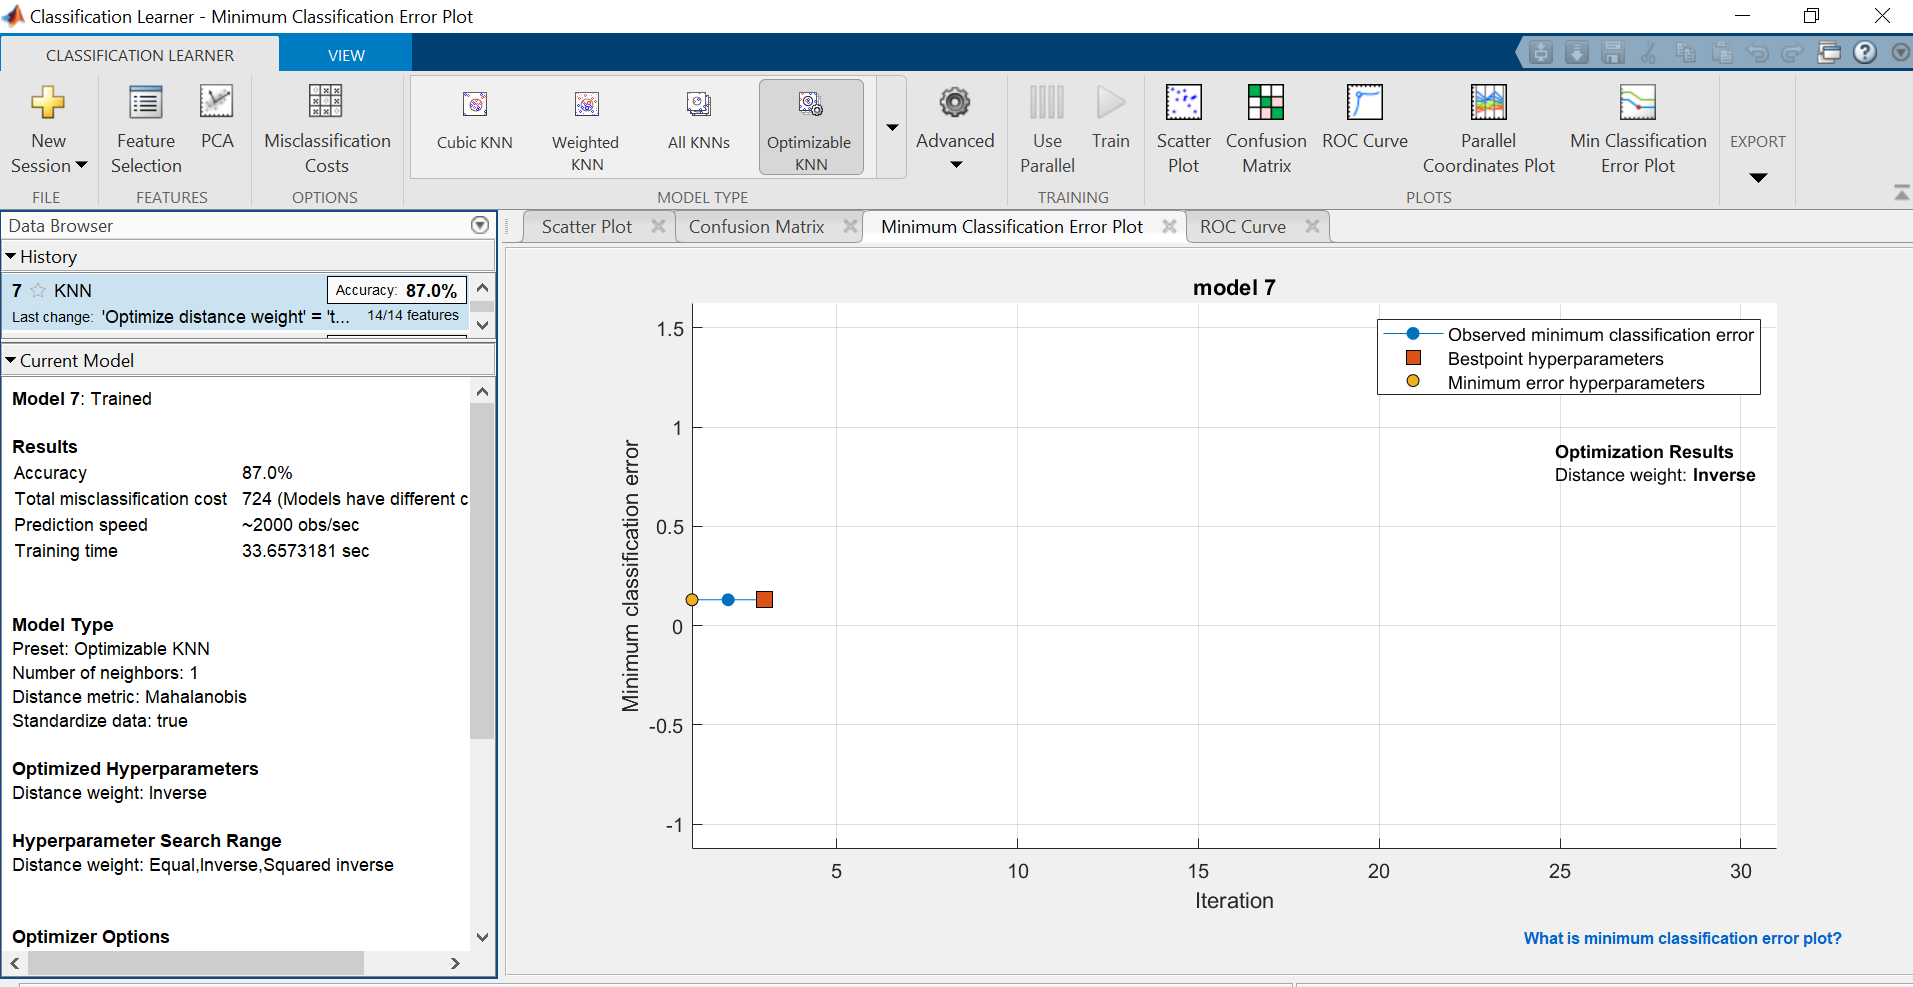

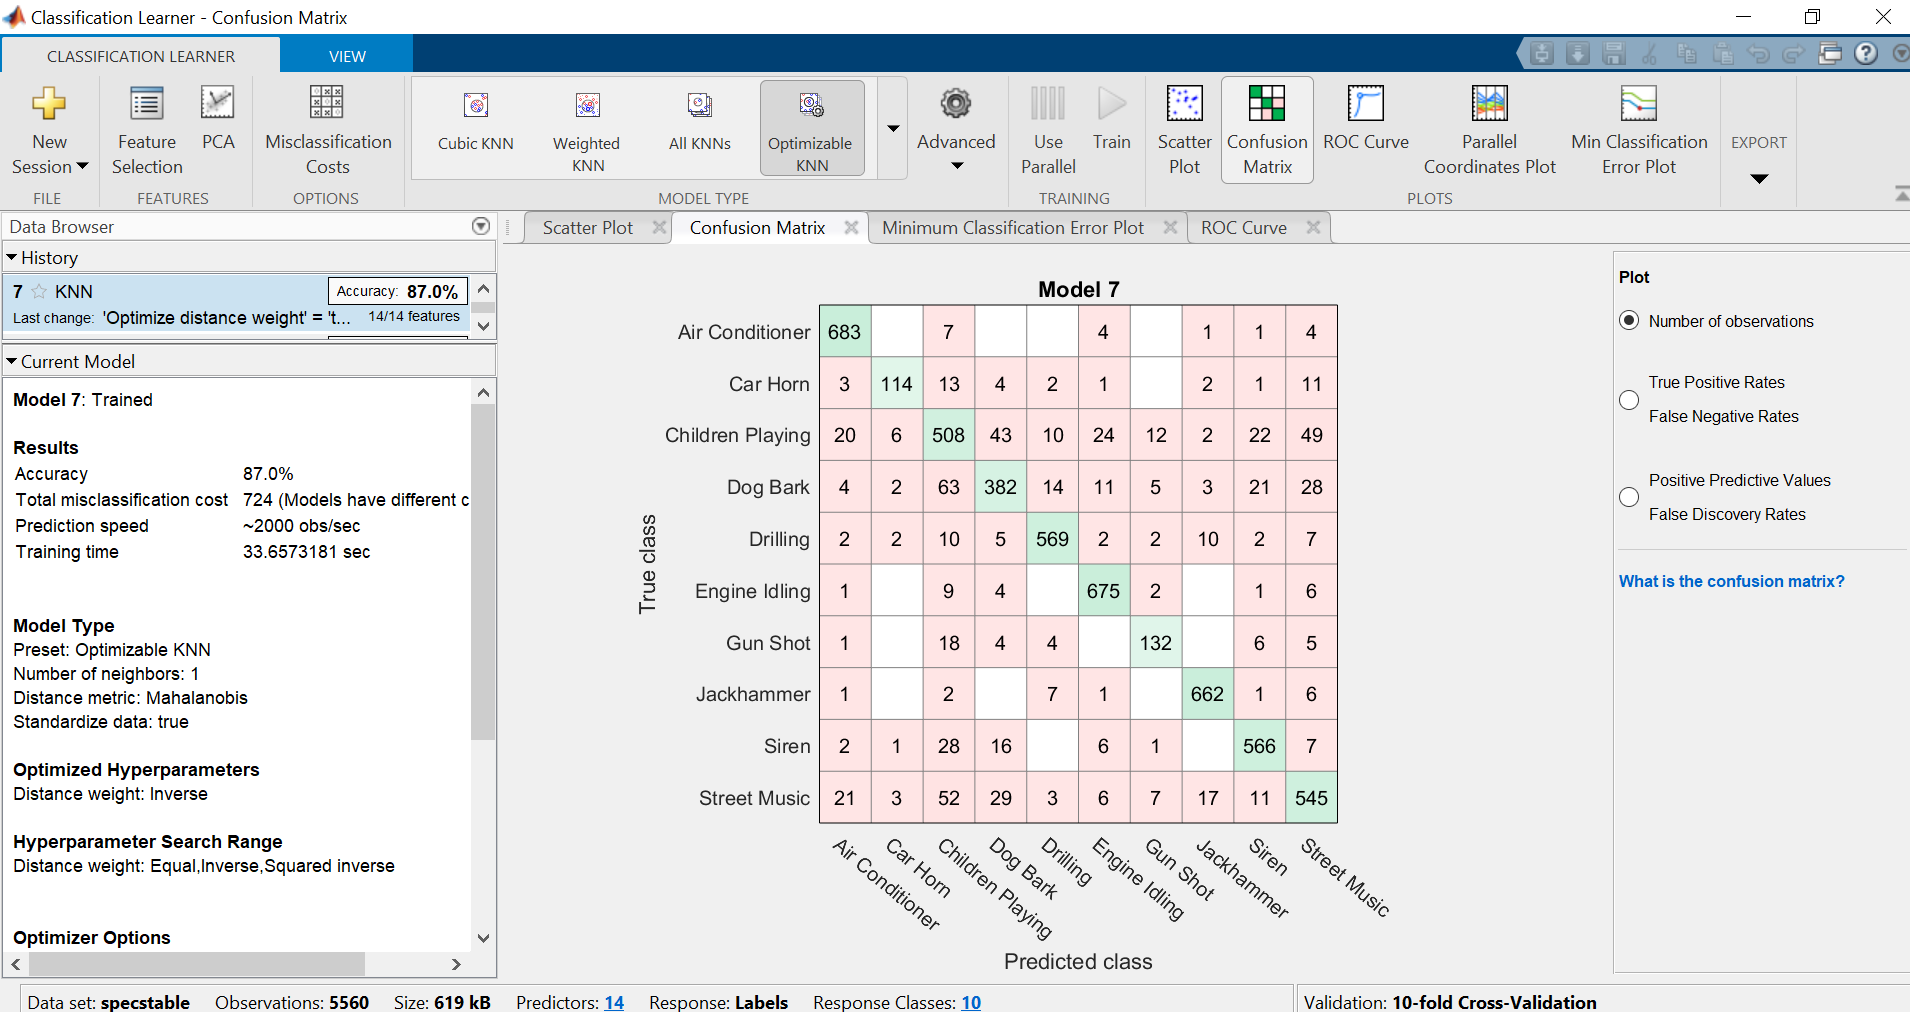

save model

save mymodel2.mat trainedModel

## **Verify with testing dataset**

- Extract features from testing datset

fs = 44100; %44.1khz
adstall_test = tall(testDatastore);
% melspectrum, barkSpectrum, erbSpectrum
aFE = audioFeatureExtractor('SampleRate',44.1e3,'mfcc',true,'pitch',true, ...
    "Window",hamming(round(fs),"periodic"), ...
    "OverlapLength",round(0.5*fs));
specsTall_test = cellfun(@(x)extract(aFE,x),adstall_test,"UniformOutput",false);
specstest = gather(specsTall_test);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3 min 3 sec
Evaluation completed in 3 min 3 sec


for i = 1:1:length(specstest)
    specs_new_test{i,1} = nanmean(specstest{i});
end

x1 = cell2mat(specs_new_test(1));
specstabletest = array2table(x1);
specstabletest.Labels(1) = testDatastore.Labels(1);
specstabletest.Files(1) = testDatastore.Files(1);
for i=2:length(specs_new_test)
    x1 = cell2mat(specs_new_test(i));
    specstable_temp_test = array2table(x1);
    specstable_temp_test.Labels = testDatastore.Labels(i);
    specstable_temp_test.Files = testDatastore.Files(i);
    try 
        specstabletest = [specstabletest;specstable_temp_test];
    end
end

specstabletest.Properties.VariableNames{1} = 'x1';
specstabletest.Properties.VariableNames{2} = 'x2';
specstabletest.Properties.VariableNames{3} = 'x3';
specstabletest.Properties.VariableNames{4} = 'x4';
specstabletest.Properties.VariableNames{5} = 'x5';
specstabletest.Properties.VariableNames{6} = 'x6';
specstabletest.Properties.VariableNames{7} = 'x7';
specstabletest.Properties.VariableNames{8} = 'x8';
specstabletest.Properties.VariableNames{9} = 'x9';
specstabletest.Properties.VariableNames{10} = 'x10';
specstabletest.Properties.VariableNames{11} = 'x11';
specstabletest.Properties.VariableNames{12} = 'x12';
specstabletest.Properties.VariableNames{13} = 'x13';
specstabletest.Properties.VariableNames{14} = 'x14';

- Prediction with testing dataset

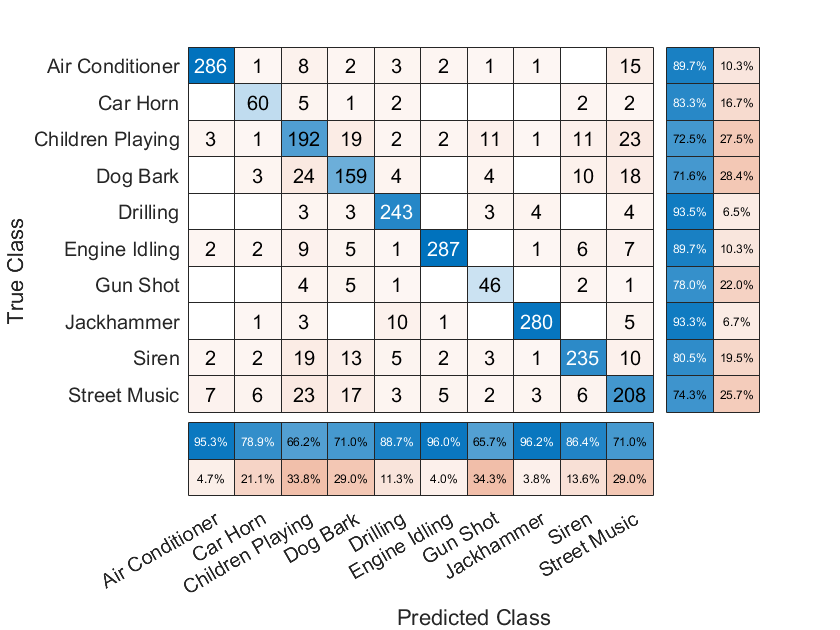

[predictionoutcome,scores]=trainedModel.predictFcn(specstabletest);
fig = figure;
cm = confusionchart(string(predictionoutcome),string(specstabletest.Labels),'RowSummary','row-normalized','ColumnSummary','column-normalized');

accuracy=sum(string(predictionoutcome)==string(specstabletest.Labels))/length(specstabletest.Labels)

accuracy =    0.835496023440770


## **Further Improvement with aggregated model**

- I notice missclassification are mainly happened between children playing, dog bark and and street music. Now i'm going to implement aggragted approach, which if the outcome from our model is children playing/dog bark/street music, then they will be classified again with another model (the model is only trained to classify this 3 classification).

- Add some time-domain features for second model

        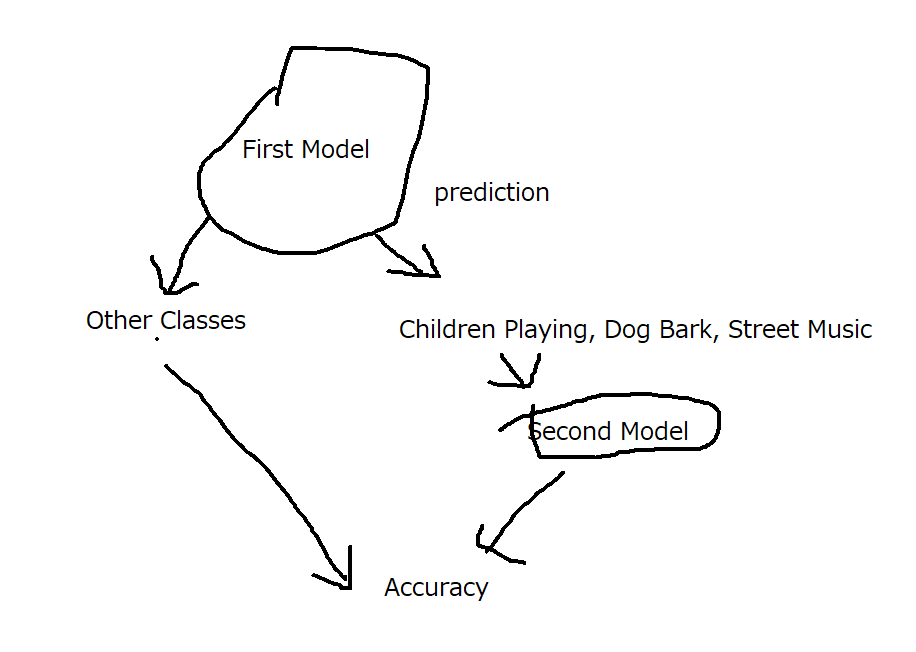

extract train data (classes = children playing, dog bark and street music)

clearvars ShapeFactor Kurtosis Skew PeakValue CrestFactor ImpulseFactor ClearanceFactor
children=specstable(strcmp(string(specstable.Labels),'Children Playing'),:);
dog=specstable(strcmp(string(specstable.Labels),'Dog Bark'),:);
music=specstable(strcmp(string(specstable.Labels),'Street Music'),:);
gun=specstable(strcmp(string(specstable.Labels),'Gun Shot'),:);
predict2table = [children;dog;music;gun];
for i = 1:1:height(predict2table)
    New_Signal = audioread(predict2table.Files{i});
    % Shape factor
    RMS = rms(New_Signal); %Root mean square
    ShapeFactor(i) = RMS/mean(abs(New_Signal)); %shape factor (RMS/Mean of absolute value)
    %Higher order statistic
    Kurtosis(i) = kurtosis(New_Signal);%Kurtois
    Skew(i)= skewness(New_Signal);%Skweness
    %Impulsive Metrics
    PeakValue(i) = max(New_Signal);%Peak value
    CrestFactor(i) = peak2rms(New_Signal);%Crest Factor %Ratio of absolute value to rms
    ImpulseFactor(i) = PeakValue(i)/mean(abs(New_Signal));%Impulse Factor %Ratio of maximum absolute value to the mean of the absolute value 
    ClearanceFactor(i) = PeakValue(i)/(mean(sqrt(abs((New_Signal)))))^2;%Clearance Factor %Ratio of the maximum absolute value to the absolute value's square root  
end

predict2table.ShapeFactor = ShapeFactor';
predict2table.Kurtosis = Kurtosis';
predict2table.Skew = Skew';
predict2table.PeakValue = PeakValue';
predict2table.CrestFactor = CrestFactor';
predict2table.ImpulseFactor = ImpulseFactor';
predict2table.ClearanceFactor = ClearanceFactor';

Train second model 

classificationLearner

Result : 

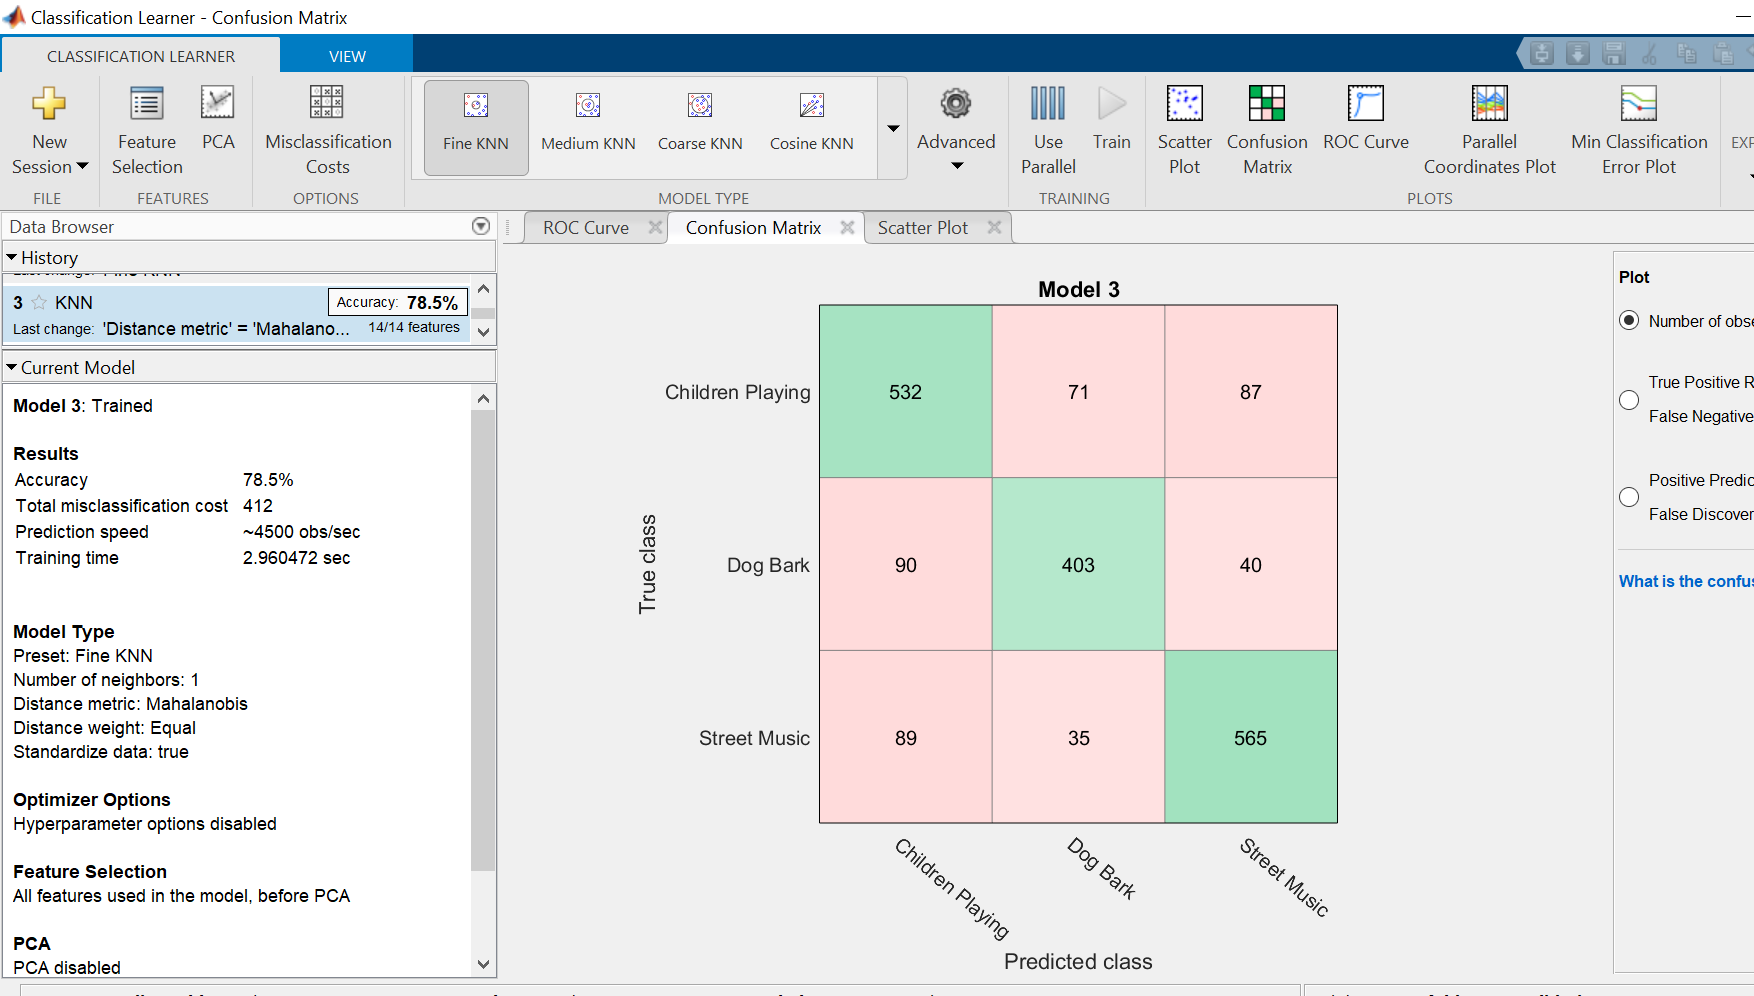

save model

save mymodel3.mat trainedModel7

clearvars ShapeFactor Kurtosis Skew PeakValue CrestFactor ImpulseFactor ClearanceFactor
for i = 1:1:height(specstabletest)
    New_Signal = audioread(specstabletest.Files{i});
    % Shape factor
    RMS = rms(New_Signal); %Root mean square
    ShapeFactor(i) = RMS/mean(abs(New_Signal)); %shape factor (RMS/Mean of absolute value)
    %Higher order statistic
    Kurtosis(i) = kurtosis(New_Signal);%Kurtois
    Skew(i)= skewness(New_Signal);%Skweness
    %Impulsive Metrics
    PeakValue(i) = max(New_Signal);%Peak value
    CrestFactor(i) = peak2rms(New_Signal);%Crest Factor %Ratio of absolute value to rms
    ImpulseFactor(i) = PeakValue(i)/mean(abs(New_Signal));%Impulse Factor %Ratio of maximum absolute value to the mean of the absolute value 
    ClearanceFactor(i) = PeakValue(i)/(mean(sqrt(abs((New_Signal)))))^2;%Clearance Factor %Ratio of the maximum absolute value to the absolute value's square root  
end

specstabletest.ShapeFactor = ShapeFactor';
specstabletest.Kurtosis = Kurtosis';
specstabletest.Skew = Skew';
specstabletest.PeakValue = PeakValue';
specstabletest.CrestFactor = CrestFactor';
specstabletest.ImpulseFactor = ImpulseFactor';
specstabletest.ClearanceFactor = ClearanceFactor';

verify the accuracy with testing dataset (go through 2 model)

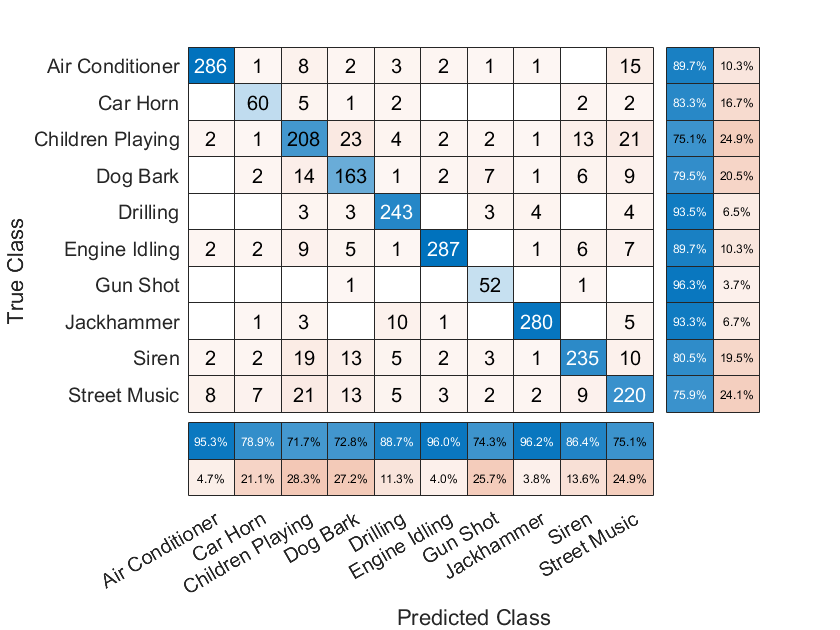

[predictionoutcome,scores]=trainedModel.predictFcn(specstabletest);
for i = 1:1:length(predictionoutcome)
    if strcmp(string(predictionoutcome(i)),"Children Playing") || strcmp(string(predictionoutcome(i)),"Dog Bark") || strcmp(string(predictionoutcome(i)),"Street Music") || strcmp(string(predictionoutcome(i)),"Gun Shot")
        predictionoutcome(i)=trainedModel7.predictFcn(specstabletest(i,:));
    end
end
fig = figure;
cm = confusionchart(string(predictionoutcome),string(specstabletest.Labels),'RowSummary','row-normalized','ColumnSummary','column-normalized');

accuracy=sum(string(predictionoutcome)==string(specstabletest.Labels))/length(specstabletest.Labels)

accuracy =    0.851402260359983
